## Задание 1. Компенсирующий регулятор по состоянию.

function [eigenvalues, controllability_result] = analyze_controllability(A, B)
    eigenvalues = eig(A);
    controllability_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A, B]
        rank_H = rank(H)
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            controllability_result = false;
            fprintf(' is not controllable.\n');
        else
            fprintf(' is controllable.\n');
        end
    end
    
    if controllability_result
        disp('The system is fully controllable.');
    else
        disp('The system is not fully controllable.');
    end
end

function [J1, Bj, P1] = j_stuff_B(A, B)
    [P, J] = jordan(A);
    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    % disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица B:');
    Bj = P1\B;
    disp(Bj); 
end

function observable(A, C)
    Ob = obsv(A, C)
    rank_Ob = rank(Ob)
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end

function [K] = get_K(A, B, G, Y)
    % Solve for K using CVX    
    cvx_begin sdp
        variable P(size(A, 1), size(A, 1))
        A*P-P*G == B*Y;
    cvx_end
    K = -Y*pinv(P);
end

function [K2] = get_K2(A, B1, B2, G, C, D, K1)
    cvx_begin sdp
        variable P(size(A, 1), size(G, 1))
        variable Y(size(B1, 2), size(B2, 2))
        P*G-A*P==B1*Y+B2;
        C*P==-D;
    cvx_end
    K2 = Y-K1*P;
end

function sim_sys(A, B, Bf, K1, K2, G, x0, wf0, simtime)
    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'Bf', Bf);
    assignin('base', 'K1', zeros(size(K1)));
    assignin('base', 'K2', zeros(size(K2)));
    assignin('base', 'G', G);
    assignin('base', 'x0', x0);
    assignin('base', 'wf0', wf0);

    % Simulink model name
    model_name = 'task1';
    load_system(model_name);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t = sim_out.tout;
    x = sim_out.yout{1}.Values.Data;
    wf = sim_out.yout{3}.Values.Data;
    z = sim_out.yout{4}.Values.Data;

    % No control
    figure('Position', [0 0 500 900]);

    m = 3;

    subplot(m, 1, 1);
    plot(t, wf, 'LineWidth', 1.5);
    title('Внешнее возмущение');
    xlabel('Время, с');
    ylabel('w_f(t)');
    legend("w_1", "w_2", "w_3", "w_4", 'Location', 'eastoutside');
    grid on;

    subplot(m, 1, 2);
    plot(t, x, 'LineWidth', 1.5);
    title('Состояние');
    xlabel('Время, с');
    ylabel('x(t)');
    legend("x_1", "x_2", "x_3", 'Location', 'eastoutside');
    grid on;

    subplot(m, 1, 3);
    plot(t, z, 'LineWidth', 1.5);
    title('Виртуальный выход');
    xlabel('Время, с');
    ylabel('z(t)');
    grid on;

    exportgraphics(gcf, ['figs/task1_1.png'], 'Resolution', 500);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    assignin('base', 'K1', K1);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation resuщиыукlts
    t1 = sim_out.tout;
    x1 = sim_out.yout{1}.Values.Data;
    u1 = sim_out.yout{2}.Values.Data;
    z1 = sim_out.yout{4}.Values.Data;

    assignin('base', 'K2', K2);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t2 = sim_out.tout;
    x2 = sim_out.yout{1}.Values.Data;
    u2 = sim_out.yout{2}.Values.Data;
    z2 = sim_out.yout{4}.Values.Data;

    figure('Position', [0 0 900 900]);

    m = 3;
    n = 3;

    subplot(m, n, [1,2,3]);
    plot(t1, u1, 'LineWidth', 1.5); hold on;
    plot(t2, u2, 'LineWidth', 1.5);
    title('Управление');
    xlabel('Время, с');
    ylabel('u(t)');
    legend("K1", "K1   K2", 'Location', 'eastoutside');
    grid on;

    subplot(m, n, 4);
    plot(t1, x1(:, 1), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 1), 'LineWidth', 1.5);
    title('Состояние 1');
    xlabel('Время, с');
    ylabel('x_1(t)');
    grid on;

    subplot(m, n, 5);
    plot(t1, x1(:, 2), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 2), 'LineWidth', 1.5);
    title('Состояние 2');
    xlabel('Время, с');
    ylabel('x_2(t)');
    grid on;

    subplot(m, n, 6);
    plot(t1, x1(:, 3), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 3), 'LineWidth', 1.5);
    title('Состояние 3');
    xlabel('Время, с');
    ylabel('x_3(t)');
    grid on;

    subplot(m, n, [7,8,9]);
    plot(t1, z1, 'LineWidth', 1.5); hold on;
    plot(t2, z2, 'LineWidth', 1.5);
    title('Виртуальный выход');
    xlabel('Время, с');
    ylabel('z(t)');
    grid on;

    exportgraphics(gcf, ['figs/task1_2.png'], 'Resolution', 500);
end

A = [        3 5 4;
        -2 -4 -5;
        2 2 3];
B = [2;-1;1];
Bf = [        -2 0 0 2;
        -2 0 0 0;
        0 0 0 0];
G = [        35 56 22 -42;
        -11 -17 -7 12;
        -6 -10 -5 10;
        11 18 6 -13];
CZ = [2 3 3];

eig(G)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i


analyze_controllability(A, B);

Eigenvalues of A:
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i



H =   -1.0000 + 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 + 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 1.0000i   1.0000 + 0.0000i


rank_H = 3

Eigenvalue 2 1.000000e+00i is controllable.


H =   -1.0000 - 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 - 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 - 1.0000i   1.0000 + 0.0000i


rank_H = 3

Eigenvalue 2 -1.000000e+00i is controllable.


H =    -5.0000   -5.0000   -4.0000    2.0000
    2.0000    2.0000    5.0000   -1.0000
   -2.0000   -2.0000   -5.0000    1.0000


rank_H = 2

Eigenvalue -2.000000e+00 0i is not controllable.
The system is not fully controllable.


[AJ, BJ, P] = j_stuff_B(A, B);

Вещественная жорданова форма матрицы A:
    -2     0     0
     0     2    -1
     0     1     2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
         0
    0.7071
   -2.1213



Aj = [2 -1;
    1 2];
Bj = [0.7071; -2.1213];
Gr = [-10 1;
    0 -10];
Y = [1 0];
observable(Gr, Y)

Ob =      1     0
   -10     1


rank_Ob = 2

YES


Kj = get_K(Aj, Bj, Gr, Y)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


Kj =   -64.0645  -10.0410


KJ = [0 Kj];
eig(AJ+BJ*KJ)

ans =    -9.9628
  -10.0374
   -2.0000


K=KJ/P

K =    14.2001   14.2001  -38.2004


eig(A+B*K)

ans =    -9.9628
  -10.0374
   -2.0000


K2 = get_K2(A, B, Bf, G, CZ, 0, K)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.8e-01|2.9e+03|5.2e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.894|3.4e-02|3.1e+02|1.6e+04| 0.000000e+00  3.766264e+03| 0:0:00| chol  1  2 
 2|1.000|0.982|8.0e-05|5.6e+00|1.5e+02| 0.000000e+00  5.872763e+01| 0:0:00| chol  1  1 
 3|1.000|0.989|1.7e-06|6.3e-02|1.4e+00| 0.000000e+00  6.770703e-01| 0:0:00| chol  1  1 
 4|1.000|0.98

K2 =  -616.3844 -913.3667 -408.5065  751.0739


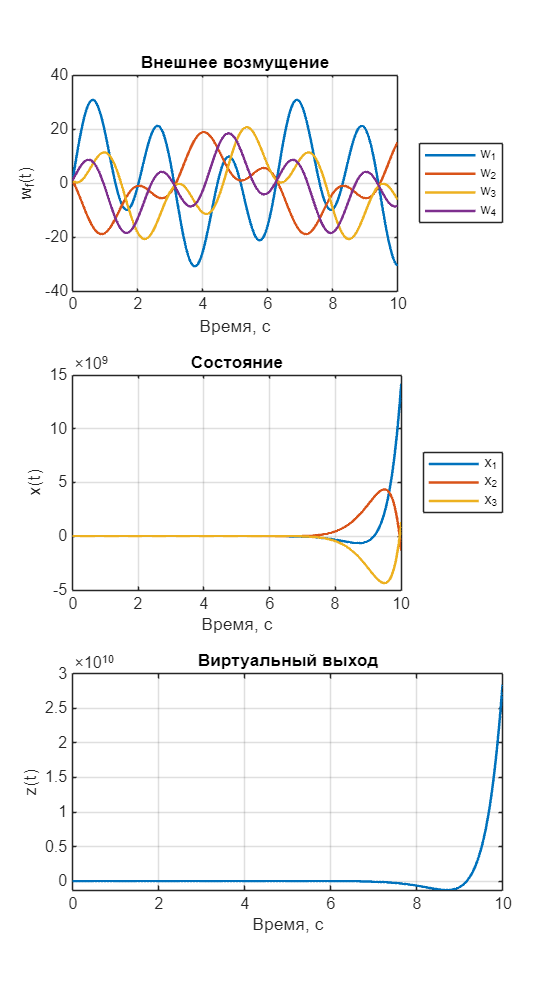

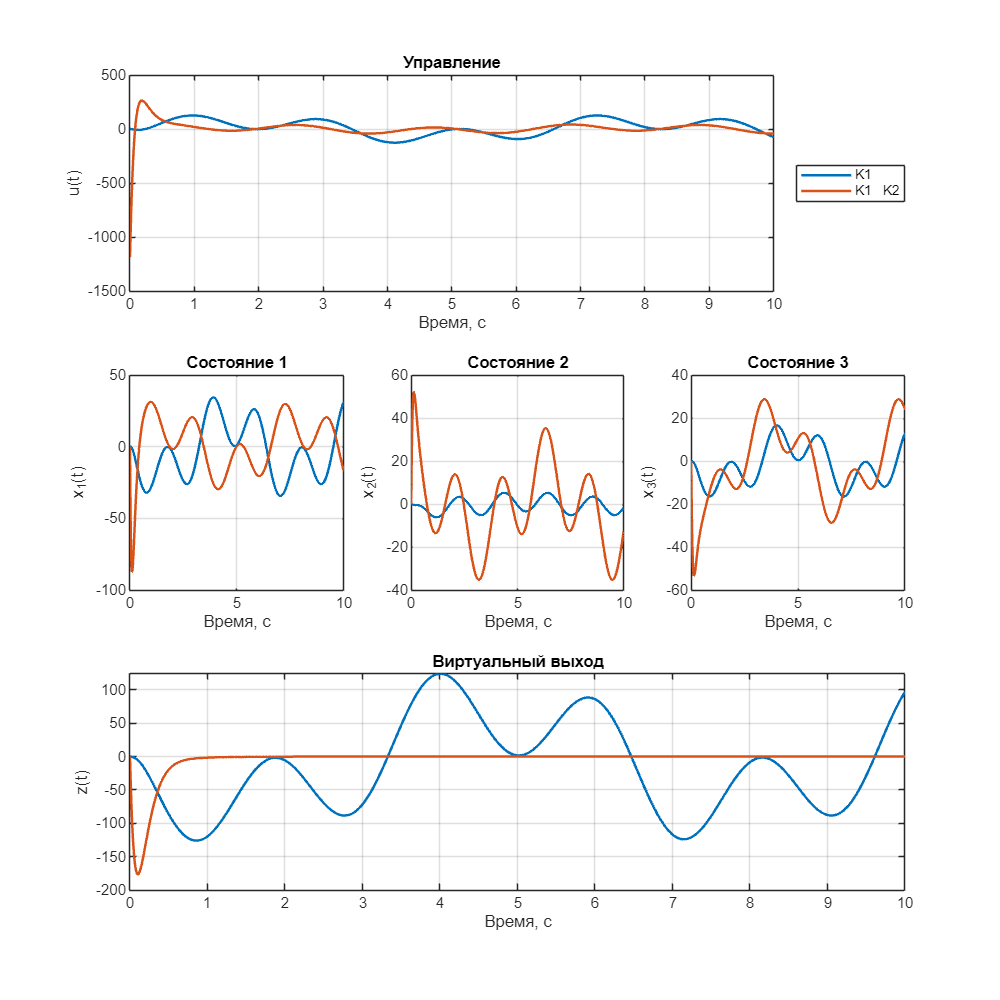

x0 = [0; 0; 0];
wf0 = [1; 1; 1; 1];
sim_sys(A, B, Bf, K, K2, G, x0, wf0, 10);

## Задание 2. Следящий регулятор по состоянию.

function sim_sys2(A, B, K1, K2, G, x0, wg0, simtime)
    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'K1', zeros(size(K1)));
    assignin('base', 'K2', zeros(size(K2)));
    assignin('base', 'G', G);
    assignin('base', 'x0', x0);
    assignin('base', 'wg0', wg0);

    % Simulink model name
    model_name = 'task2';
    load_system(model_name);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t = sim_out.tout;
    x = sim_out.yout{1}.Values.Data;
    wg = sim_out.yout{3}.Values.Data;
    z = sim_out.yout{4}.Values.Data;

    % No control
    figure('Position', [0 0 500 900]);

    m = 3;

    subplot(m, 1, 1);
    plot(t, wg, 'LineWidth', 1.5);
    title('Внешнее возмущение');
    xlabel('Время, с');
    ylabel('w_f(t)');
    legend("w_1", "w_2", "w_3", "w_4", 'Location', 'eastoutside');
    grid on;

    subplot(m, 1, 2);
    plot(t, x, 'LineWidth', 1.5);
    title('Состояние');
    xlabel('Время, с');
    ylabel('x(t)');
    legend("x_1", "x_2", "x_3", 'Location', 'eastoutside');
    grid on;

    subplot(m, 1, 3);
    plot(t, z, 'LineWidth', 1.5);
    title('Виртуальный выход');
    xlabel('Время, с');
    ylabel('z(t)');
    grid on;

    exportgraphics(gcf, ['figs/task2_1.png'], 'Resolution', 500);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    assignin('base', 'K1', K1);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t1 = sim_out.tout;
    x1 = sim_out.yout{1}.Values.Data;
    u1 = sim_out.yout{2}.Values.Data;
    z1 = sim_out.yout{4}.Values.Data;

    assignin('base', 'K2', K2);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t2 = sim_out.tout;
    x2 = sim_out.yout{1}.Values.Data;
    u2 = sim_out.yout{2}.Values.Data;
    z2 = sim_out.yout{4}.Values.Data;

    figure('Position', [0 0 900 900]);

    m = 3;
    n = 3;

    subplot(m, n, [1,2,3]);
    plot(t1, u1, 'LineWidth', 1.5); hold on;
    plot(t2, u2, 'LineWidth', 1.5);
    title('Управление');
    xlabel('Время, с');
    ylabel('u(t)');
    legend("K1", "K1   K2", 'Location', 'eastoutside');
    grid on;

    subplot(m, n, 4);
    plot(t1, x1(:, 1), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 1), 'LineWidth', 1.5);
    title('Состояние 1');
    xlabel('Время, с');
    ylabel('x_1(t)');
    grid on;

    subplot(m, n, 5);
    plot(t1, x1(:, 2), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 2), 'LineWidth', 1.5);
    title('Состояние 2');
    xlabel('Время, с');
    ylabel('x_2(t)');
    grid on;

    subplot(m, n, 6);
    plot(t1, x1(:, 3), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 3), 'LineWidth', 1.5);
    title('Состояние 3');
    xlabel('Время, с');
    ylabel('x_3(t)');
    grid on;

    subplot(m, n, [7,8,9]);
    plot(t1, z1, 'LineWidth', 1.5); hold on;
    plot(t2, z2, 'LineWidth', 1.5);
    title('Виртуальный выход');
    xlabel('Время, с');
    ylabel('z(t)');
    grid on;

    exportgraphics(gcf, ['figs/task2_2.png'], 'Resolution', 500);
end

A = [        3 5 4;
        -2 -4 -5;
        2 2 3];
B = [2;-1;1];
DZ = [3 4 2 -3];
G = [        35 56 22 -42;
        -11 -17 -7 12;
        -6 -10 -5 10;
        11 18 6 -13];
CZ = [2 3 3];

K2 = get_K2(A, B, zeros(size(B, 1), size(G, 2)), G, CZ, DZ, K)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.6e-01|2.9e+03|5.2e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  2 
 1|1.000|0.981|1.2e-03|5.5e+01|2.2e+03| 0.000000e+00  1.646710e+01| 0:0:00| chol  1  2 
 2|1.000|0.988|5.3e-05|6.5e-01|7.2e+00| 0.000000e+00  2.000121e-01| 0:0:00| chol  1  1 
 3|1.000|0.990|6.8e-07|7.7e-03|4.2e-02| 0.000000e+00  3.925952e-03| 0:0:00| chol  2  2 
 4|1.000|0.99

K2 =    90.7624  145.6219   64.7442 -109.6806


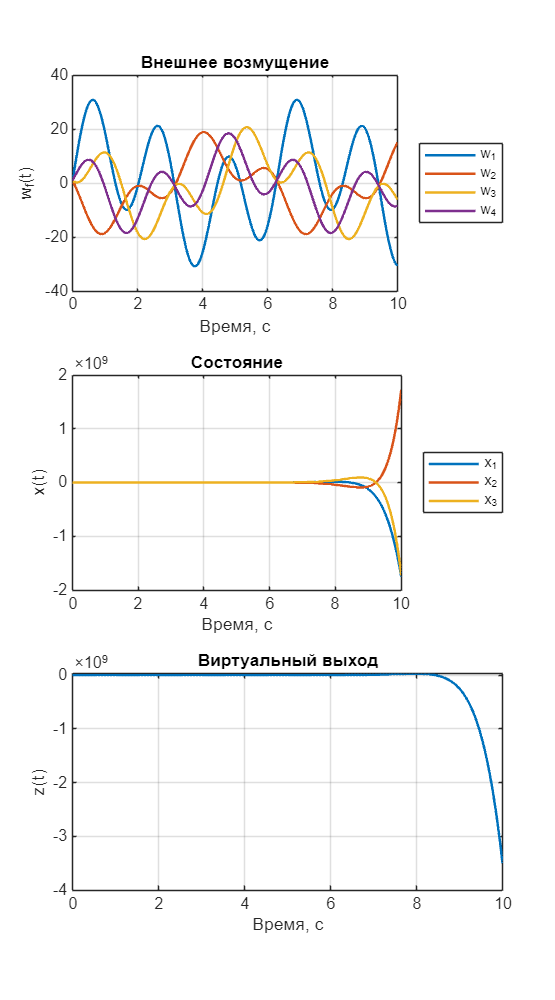

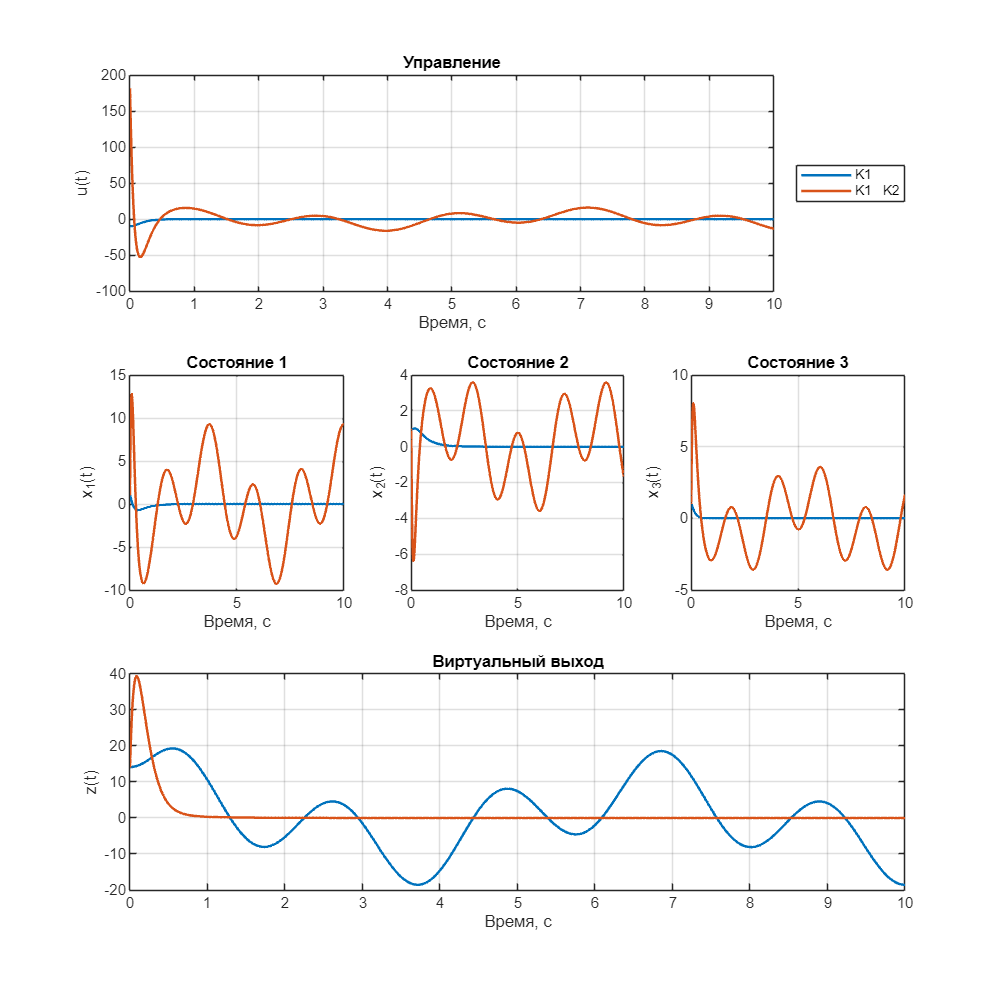

x0 = [1; 1; 1];
wg0 = [1; 1; 1; 1];
sim_sys2(A, B, K, K2, G, x0, wg0, 10);

## Задание 3. Слежение и компенсация по выходу.

function [L] = get_L(A, C, G, Y)
    % Solve for K using CVX    
    cvx_begin sdp
        variable Q(size(A, 1), size(A, 1))
        G*Q-Q*A == Y*C;
    cvx_end
    L = pinv(Q)*Y;
end
function controllable(A, B)
    Co = ctrb(A, B);
    rank_Co = rank(Co);
    if rank_Co == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end

A = [3 5 4;
    -2 -4 -5;
     2 2 3];
B = [2;-1;1];
Bf = [-2 0 0 2;
      -2 0 0 0;
       0 0 0 0];
G = [    35 56 22 -42;
        -11 -17 -7 12;
        -6 -10 -5 10;
         11 18 6 -13];
CZ = [2 3 3];
DZ = [3 4 2 -3];
C = [-2 -1 0];
D = [1 2 1 -1];
Ao = [A Bf; zeros(4, 3) G]

Ao =      3     5     4    -2     0     0     2
    -2    -4    -5    -2     0     0     0
     2     2     3     0     0     0     0
     0     0     0    35    56    22   -42
     0     0     0   -11   -17    -7    12
     0     0     0    -6   -10    -5    10
     0     0     0    11    18     6   -13


Co = [C D]

Co =     -2    -1     0     1     2     1    -1


observable(Ao, Co)

Ob =           -2          -1           0           1           2           1          -1
          -4          -6          -3           2          -6          -3           1
          -6          -2           5         185         262         107        -207
          -4         -12           1         690        1110         459        -877
          14          30          47        -429        -606        -147         323
          76          44          47       -4002       -6438       -2523        5105
         234         298         225        1801        2454         267        -615


rank_Ob = 7

YES


Go = [-10 1 0 0 0 0 0;
      0 -10 1 0 0 0 0;
      0 0 -10 1 0 0 0;
      0 0 0 -10 1 0 0;
      0 0 0 0 -10 1 0;
      0 0 0 0 0 -10 1;
      0 0 0 0 0 0 -10]

Go =    -10     1     0     0     0     0     0
     0   -10     1     0     0     0     0
     0     0   -10     1     0     0     0
     0     0     0   -10     1     0     0
     0     0     0     0   -10     1     0
     0     0     0     0     0   -10     1
     0     0     0     0     0     0   -10


Y = [0; 0; 0; 0; 0; 0; 1]

Y =      0
     0
     0
     0
     0
     0
     1


controllable(Go, Y)

YES


L = get_L(Ao, Co, Go, Y)

 
Calling SDPT3 4.0: 31 variables, 31 equality constraints
------------------------------------------------------------

 num. of constraints = 31
 dim. of linear var  =  1
 dim. of free   var  = 31 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.1e-01|5.3e+03|2.6e+06| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.989|3.0e-08|6.0e+01|5.8e+03| 0.000000e+00  6.419770e-04| 0:0:00| chol  1  1 
 2|1.000|0.989|3.7e-08|6.6e-01|1.3e+01| 0.000000e+00  2.226026e-05| 0:0:00| chol  1  1 
 3|1.000|0.991|2.4e-09|7.2e-03|3.0e-02| 0.000000e+00  7.509505e-06| 0:0:00| chol  1  1 
 4|1.000|1.00

L = 1.0e+05 *

   -0.6161
    1.1915
   -1.2706
    0.1181
   -0.1442
    0.0609
   -0.0680


K1 = [14.2001 14.2001 -38.2004];
%K2 = get_K2(A, B, Bf, G, CZ, DZ, K1)

%A_bar = [
%    A+B*K1+L(1:3)*C Bf+B*K2+L(1:3)*D;
%    L(4:7)*C L(4:7)*D+G
%];
%x0 = [0; 0; 0];
%w0 = [1; 1; 1; 1];
%xw0_hat = zeros(7, 1);
%YZ = 0;

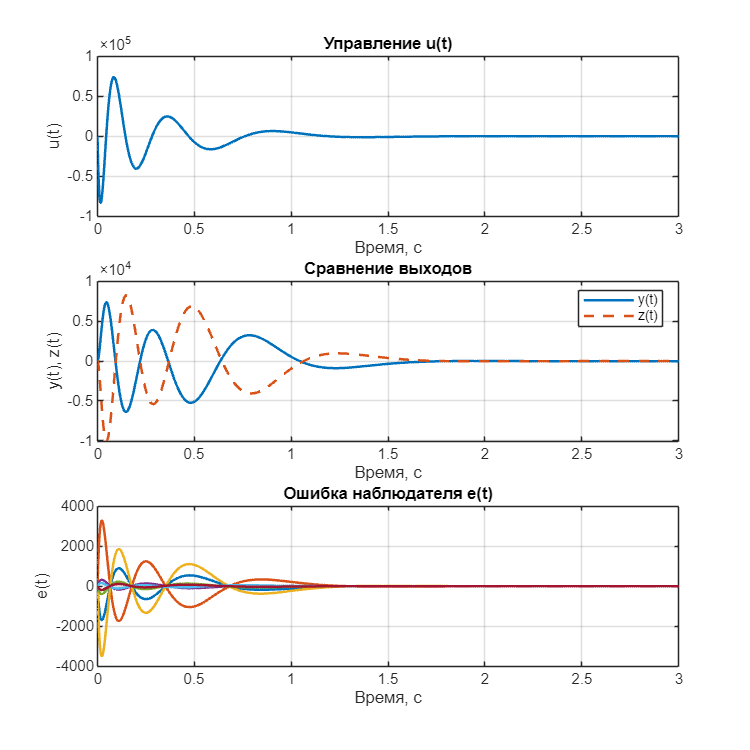

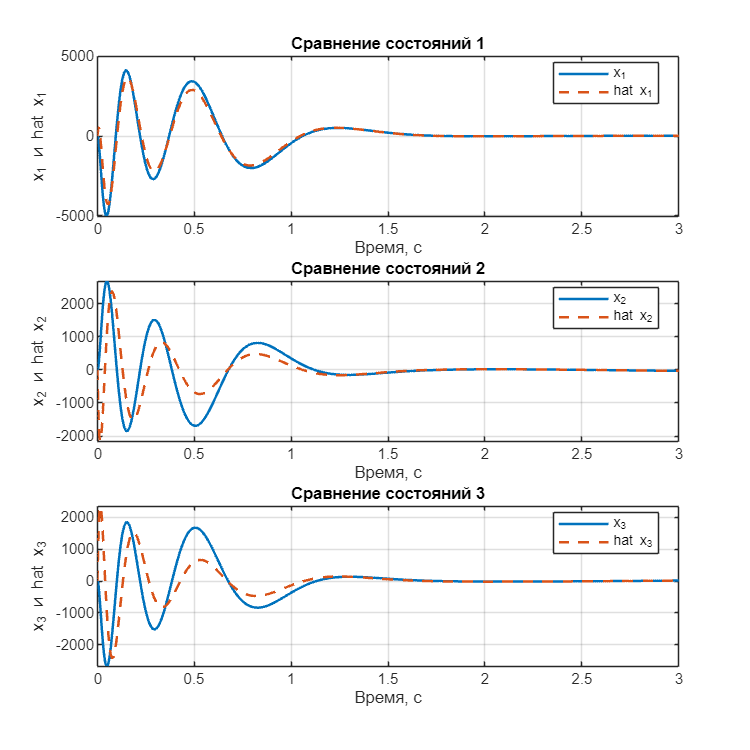

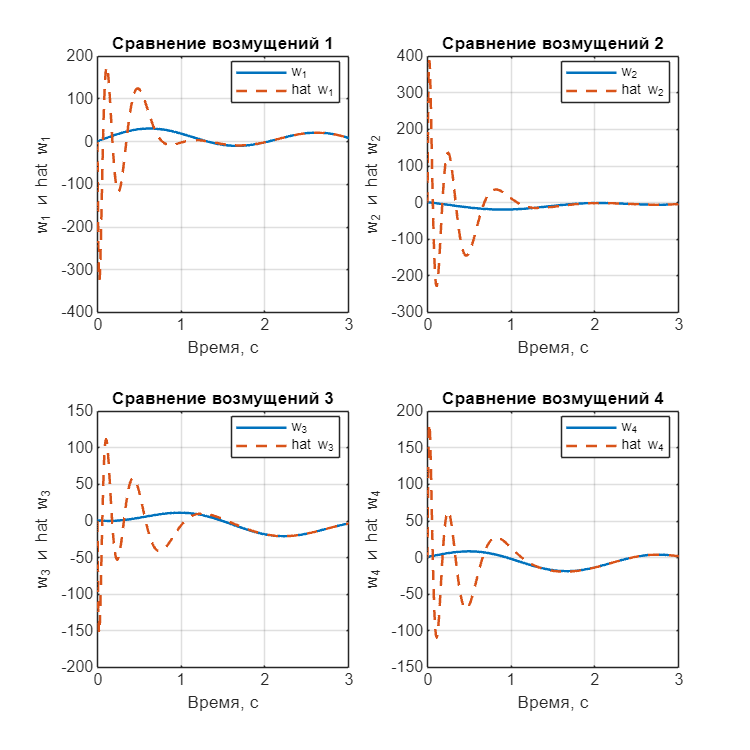

function sim_obs(A, B, Bf, K1, K2, G, L, A_bar, C, D, CZ, DZ, x0, w0, xw0_hat, simtime,id)
    % Название Simulink модели
    model_name = 'task3';
    load_system(model_name);

    % Выполнение моделирования
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Извлечение результатов моделирования
    t = sim_out.tout;
    x = sim_out.yout{1}.Values.Data;  % Реальные состояния
    u = sim_out.yout{2}.Values.Data;  % Управление
    w = sim_out.yout{3}.Values.Data;  % Выход системы
    z = sim_out.yout{4}.Values.Data;  % Виртуальный выход
    y = sim_out.yout{5}.Values.Data;  % Виртуальный выход
    xw_hat = sim_out.yout{6}.Values.Data;  % Виртуальный выход
    x_hat = xw_hat(:, 1:3);
    w_hat = xw_hat(:, 4:7);
    e = [x w] - xw_hat;  % Ошибка наблюдателя

    res1 = 600;
    res2 = 600;

    % Построение графиков
    figure('Position', [0 0 res1 res2]);
    m = 3;
    n = 1;

    % Управление
    subplot(m, n, 1); % Верхний график
    plot(t, u, 'LineWidth', 1.5);
    title('Управление u(t)');
    xlabel('Время, с');
    ylabel('u(t)');
    grid on;
    
    % Выходы y и z
    subplot(m, n, 2); % Нижний график
    plot(t, y, 'LineWidth', 1.5); hold on;
    plot(t, z, '--', 'LineWidth', 1.5);
    title('Сравнение выходов');
    xlabel('Время, с');
    ylabel('y(t), z(t)');
    legend('y(t)', 'z(t)', 'Location', 'best');
    grid on;

    % Ошибка наблюдателя
    subplot(m, n, 3); % Row 4, first half of the row
    plot(t, e, 'LineWidth', 1.5);
    title('Ошибка наблюдателя e(t)');
    xlabel('Время, с');
    ylabel('e(t)');
    grid on;

    exportgraphics(gcf, ['figs/task3_', int2str(id),  '.png'], 'Resolution', 1000);
    
    % Сравнение состояний x и x_hat
    figure('Position', [0 0 res1 res2]);
    for i = 1:3
        subplot(3, 1, i);
        plot(t, x(:, i), 'LineWidth', 1.5); hold on;
        plot(t, x_hat(:, i), '--', 'LineWidth', 1.5);
        title(['Сравнение состояний ', int2str(i)]);
        xlabel('Время, с');
        ylabel(['x_', int2str(i), ' и hat x_', int2str(i)]);
        legend(['x_', int2str(i)], ['hat x_', int2str(i)], 'Location', 'best');
        grid on;
    end

    exportgraphics(gcf, ['figs/task3_', int2str(id+1),  '.png'], 'Resolution', 1000);

    % Сравнение возмущений w и w_hat
    figure('Position', [0 0 res1 res2]);
    for i = 1:4
        subplot(2, 2, i);
        plot(t, w(:, i), 'LineWidth', 1.5); hold on;
        plot(t, w_hat(:, i), '--', 'LineWidth', 1.5);
        title(['Сравнение возмущений ', int2str(i)]);
        xlabel('Время, с');
        ylabel(['w_', int2str(i), ' и hat w_', int2str(i)]);
        legend(['w_', int2str(i)], ['hat w_', int2str(i)], 'Location', 'best');
        grid on;
    end

    % Сохранение графиков
    exportgraphics(gcf, ['figs/task3_', int2str(id+2),  '.png'], 'Resolution', 1000);
end

sim_obs(A, B, Bf, K1, K2, G, L, A_bar, C, D, CZ, DZ, x0, w0, xw0_hat, 3, 1)

eig(A_bar)

ans = 1.0e+03 *

  -0.0458 + 3.4998i
  -0.0458 - 3.4998i
   0.0000 + 0.0030i
   0.0000 - 0.0030i
  -0.0002 + 0.0011i
  -0.0002 - 0.0011i
  -0.0020 + 0.0000i


YZ = 1;
CZ = zeros(1, 3);
DZ = zeros(1, 4);
K2 = get_K2(A, B, Bf, G, CZ, DZ, K1)

 
Calling SDPT3 4.0: 16 variables, 12 equality constraints
------------------------------------------------------------

 num. of constraints = 13
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+00|2.9e+03|1.0e+06| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.984|1.7e-04|4.6e+01|3.6e+03| 0.000000e+00  3.677524e+00| 0:0:00| chol  1  1 
 2|1.000|0.989|6.1e-05|5.2e-01|1.1e+01| 0.000000e+00  5.466463e-02| 0:0:00| chol  1  1 
 3|1.000|0.989|7.4e-07|6.7e-03|6.7e-02| 0.000000e+00  4.146455e-03| 0:0:00| chol  1  1 
 4|1.000|0.98

K2 =    44.7815   42.7269   72.1761  -19.6638


A_bar = [
    A+B*K1+L(1:3)*C Bf+B*K2+L(1:3)*D;
    L(4:7)*CZ L(4:7)*DZ+G
];
% sim_obs(A, B, Bf, K1, K2, G, L, A_bar, C, D, CZ, DZ, x0, w0, xw0_hat, 3, 4)

eig(A_bar)

ans = 1.0e+03 *

   2.0262 + 3.5934i
   2.0262 - 3.5934i
  -0.0020 + 0.0000i
   0.0000 + 0.0030i
   0.0000 - 0.0030i
  -0.0000 + 0.0010i
  -0.0000 - 0.0010i


L1 = L(1:3);
L2 = L(4:7);

eig(G)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i


Abar = [A + B*K1 + L1 * C Bf + B * K2 + L1 * D; L2*C L2*D+G]

Abar = 1.0e+05 *

    1.2326    0.6165   -0.0007   -0.6153   -1.2314   -0.6147    0.6158
   -2.3832   -1.1917    0.0003    1.1911    2.3827    1.1908   -1.1913
    2.5414    1.2708   -0.0004   -1.2702   -2.5408   -1.2699    1.2704
   -0.2361   -0.1181         0    0.1184    0.2367    0.1183   -0.1185
    0.2884    0.1442         0   -0.1443   -0.2886   -0.1443    0.1443
   -0.1218   -0.0609         0    0.0609    0.1217    0.0609   -0.0608
    0.1359    0.0680         0   -0.0679   -0.1358   -0.0679    0.0678


eig(Abar)

ans = 1.0e+03 *

  -0.0463 + 4.2979i
  -0.0463 - 4.2979i
  -0.0001 + 0.0030i
  -0.0001 - 0.0030i
   0.0003 + 0.0010i
   0.0003 - 0.0010i
  -0.0020 + 0.0000i


## Задание 4. (Необязательное) Тележка и меандр.

G = [
        0    1    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  ;
       -1    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  ;
        0    0    0    3    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  ;
        0    0   -3    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  ;
        0    0    0    0    0    5    0    0    0    0    0    0    0    0    0    0    0    0    0    0  ;
        0    0    0    0   -5    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  ;
        0    0    0    0    0    0    0    7    0    0    0    0    0    0    0    0    0    0    0    0  ;
        0    0    0    0    0    0   -7    0    0    0    0    0    0    0    0    0    0    0    0    0  ;
        0    0    0    0    0    0    0    0    0    9    0    0    0    0    0    0    0    0    0    0  ;
        0    0    0    0    0    0    0    0   -9    0    0    0    0    0    0    0    0    0    0    0  ;
        0    0    0    0    0    0    0    0    0    0    0    11   0    0    0    0    0    0    0    0  ;
        0    0    0    0    0    0    0    0    0    0   -11   0    0    0    0    0    0    0    0    0  ;
        0    0    0    0    0    0    0    0    0    0    0    0    0   13    0    0    0    0    0    0  ;
        0    0    0    0    0    0    0    0    0    0    0    0   -13   0    0    0    0    0    0    0  ;
        0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   15    0    0    0    0  ;
        0    0    0    0    0    0    0    0    0    0    0    0    0    0    -15  0    0    0    0    0  ;
        0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   17    0    0  ;
        0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   -17   0    0    0  ;
        0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   19  ;
        0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   -19   0
];
A = [0 1; 0 0];
B = [0; 1];
C = [1 0];
Gr = diag([-1, -2])

Gr =     -1     0
     0    -2


Y = [1 1];
observable(Gr, Y)

Ob =      1     1
    -1    -2


rank_Ob = 2

YES


K1 = get_K(A, B, Gr, Y)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


K1 =    -2.0000   -3.0000


eig(A+B*K1)

ans =    -1.0000
   -2.0000


CZ = [-1 0];
DZ = -40/pi*[1 0 1/3 0 1/5 0 1/7 0 1/9 0 1/11 0 1/13 0 1/15 0 1/17 0 1/19 0];
K2 = get_K2(A, B, zeros(2, 20), G, CZ, DZ, K1)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


K2 =   -12.7324  -38.1972   29.7089  -38.1972   58.5690  -38.1972   85.4889  -38.1972  111.7621  -38.1972  137.7414  -38.1972  163.5623  -38.1972  189.2883  -38.1972  214.9528  -38.1972  240.5753  -38.1972


% Function for g(t)
function g_t = g(t)
    a = 10; % Amplitude
    T = 2 * pi; % Period
    t_mod = mod(t, T); % Modulo to wrap time within one period
    
    % Logical indexing to assign values based on intervals
    g_t = -a * (t_mod < T / 2) + a * (t_mod >= T / 2);
end

% Function for bar g(t)
function bar_g_t = bar_g(t)
    a = 10; % Amplitude
    N = 20; % Number of harmonics
    bar_g_t = 0; % Initialize the result
    
    % Calculate the series sum
    for n = 1:N
        coefficient = (-1)^n - 1; % Coefficient for the nth term
        bar_g_t = bar_g_t + (coefficient / n) * sin(n * t);
    end
    
    % Multiply by the prefactor
    bar_g_t = (20 / pi) * bar_g_t;
end

simtime = 10;
x0 = [0 0];
wg0 = [ 0 1 0 1 0 1 0 1 0 1 0 1 0 1 0 1 0 1 0 1 ];

% Simulink model name
model_name = 'task2';
load_system(model_name);

% Simulate the model
sim_out = sim(model_name, 'StopTime', num2str(simtime));

% Extract simulation results
t = sim_out.tout;
x = sim_out.yout{1}.Values.Data;
u = sim_out.yout{2}.Values.Data;

y = zeros(size(x, 1), 1);
for i=1:size(x,1)
    y(i, :) = C*x(i, :)';
end
y

y =          0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0008
   -0.0169
   -0.0539
   -0.0935


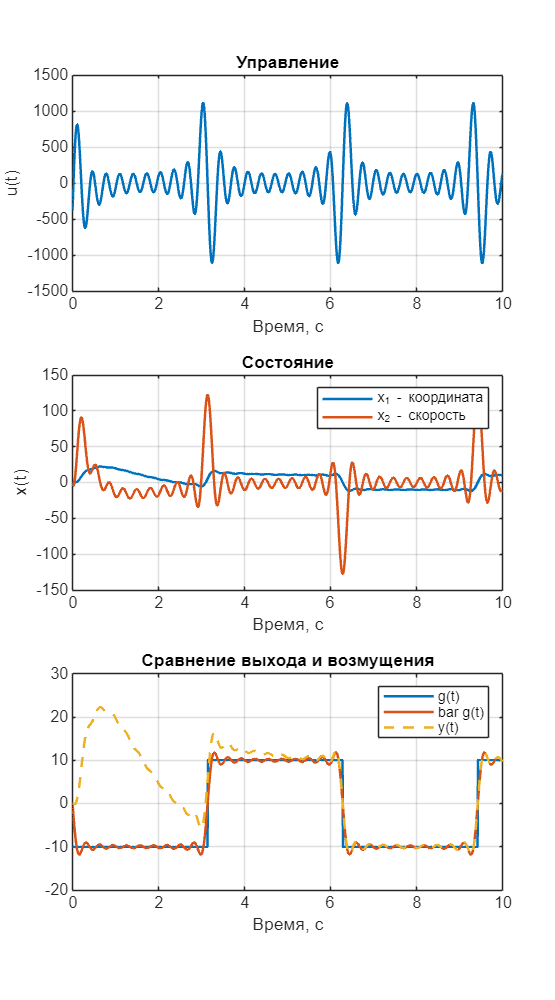


% No control
figure('Position', [0 0 500 900]);

m = 3;
n = 1;

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Время, с');
ylabel('u(t)');
grid on;

subplot(m, n, 2);
plot(t, x, 'LineWidth', 1.5); hold on;
title('Состояние');
xlabel('Время, с');
ylabel('x(t)');
legend("x_1 - координата", "x_2 - скорость")
grid on;

subplot(m, n, 3);
plot(t, g(t), 'LineWidth', 1.5); hold on;
plot(t, bar_g(t), 'LineWidth', 1.5);
plot(t, y, '--', 'LineWidth', 1.5);
title('Сравнение выхода и возмущения');
xlabel('Время, с');
legend("g(t)", "bar g(t)", "y(t)")
grid on;

exportgraphics(gcf, ['figs/task4.png'], 'Resolution', 500);